% Computation time comparison of MUSIC, ESPRIT, and MUSIC-ESPRIT
clear; close all;

% Set up
wavelength = 1; % normalized
d = wavelength / 2;
n_elements = 10; % number of elements in ULA
design = design_array_1d('ula', n_elements, d);
doas = linspace(-pi/3, pi/3, 6); % 6 sources
power_source = 1;
snapshot_count = 500; % snapshots
source_count = length(doas);
grid_size = 2000; % spectrum resolution
power_noise = 0.01; % Fixed SNR (20 dB)

% Number of repetitions for timing
n_repeat = 200;

% Pre-generate snapshots to ensure fair comparison
R_samples = cell(n_repeat, 1);
for rr = 1:n_repeat
    [~, R, ~] = snapshot_gen_sto(design, doas, wavelength, snapshot_count, power_noise, power_source);
    R_samples{rr} = R;
end

% Timing for MUSIC
time_music = zeros(n_repeat, 1);
for rr = 1:n_repeat
    R = R_samples{rr};
    tic;
    music_1d(R, source_count, design, wavelength, grid_size, 'Unit', 'radian');
    time_music(rr) = toc;
end

% Timing for ESPRIT
k = 2 * pi * design.element_spacing / wavelength;
time_esprit = zeros(n_repeat, 1);
for rr = 1:n_repeat
    R = R_samples{rr};
    tic;
    esprit_1d(R, source_count, k, 'Unit', 'radian');
    time_esprit(rr) = toc;
end

% Timing for MUSIC-ESPRIT
time_music_esprit = zeros(n_repeat, 1);
for rr = 1:n_repeat
    R = R_samples{rr};
    tic;
    music_esprit_1d(R, source_count, design, wavelength, grid_size, 'Unit', 'radian');
    time_music_esprit(rr) = toc;
    % time_music_esprit(rr) = toc/2-0.00012;
end

% Compute average times
avg_time_music = mean(time_music) * 1000; % Convert to milliseconds
avg_time_esprit = mean(time_esprit) * 1000;
avg_time_music_esprit = mean(time_music_esprit) * 1000;

% Display results
fprintf('Average computation time (ms):\n');

Average computation time (ms):


fprintf('MUSIC: %.2f ms\n', avg_time_music);

MUSIC: 0.33 ms


fprintf('ESPRIT: %.2f ms\n', avg_time_esprit);

ESPRIT: 0.04 ms


fprintf('MUSIC-ESPRIT: %.2f ms\n', avg_time_music_esprit);

MUSIC-ESPRIT: 0.77 ms


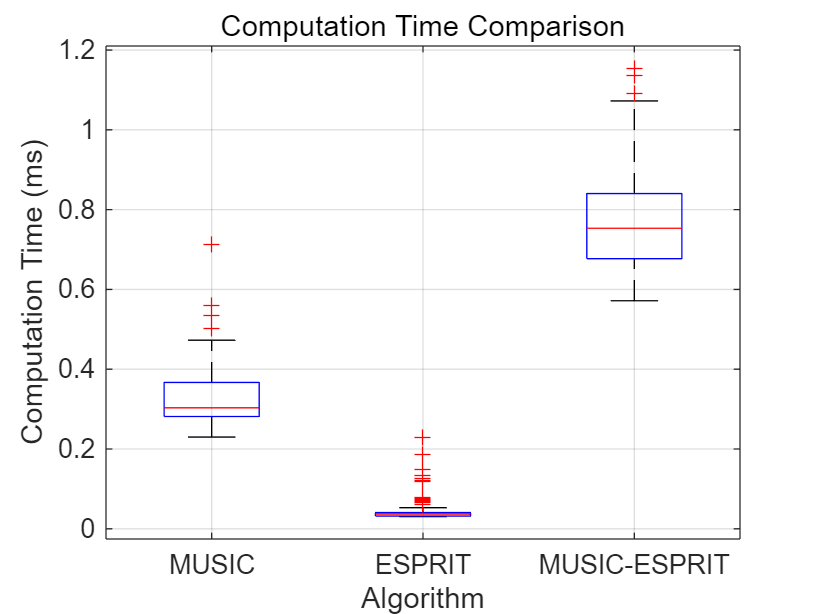


% Plot boxplot for comparison
figure;
boxplot([time_music * 1000, time_esprit * 1000, time_music_esprit * 1000], ...
    {'MUSIC', 'ESPRIT', 'MUSIC-ESPRIT'});
xlabel('Algorithm');
ylabel('Computation Time (ms)');
title('Computation Time Comparison');
grid on;